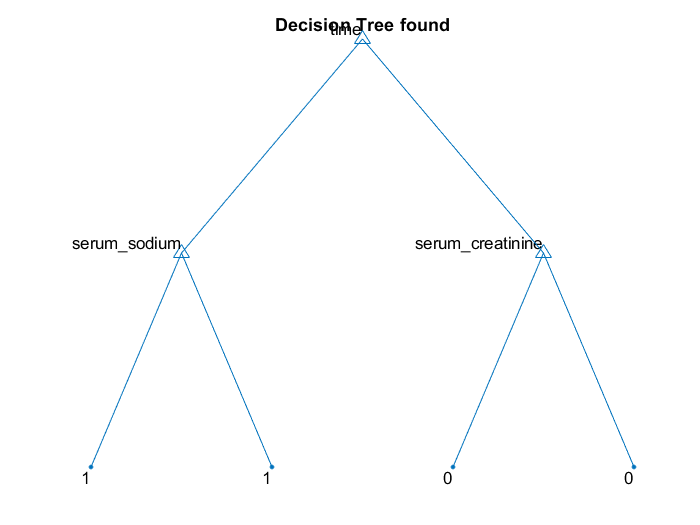

close all
clear
clc

rng(1);

addpath('./datasets');
addpath(genpath('./functions'));

heart_table = readtable('heart_failure_clinical_records_dataset.csv');
heart_mat = table2array(heart_table);
heart_mat = shuffleRows(heart_mat);

heart_X_training = heart_mat(1:240, 1:end-1);
heart_Y_training = heart_mat(1:240, end);
heart_X_test = heart_mat(241:299,1:end-1);
heart_Y_test = heart_mat(241:299,end);

%fprintf("Total Instances: %d\n", height(heart_X));
tree = decision_tree_learning(heart_X_training, heart_Y_training, "Classification", heart_table.Properties.VariableNames, 2);

DrawDecisionTree(tree);


answer = predict(tree, heart_X_test);
accuracy = myAccuracy(heart_Y_test, answer);
fprintf("Accuracy: %.2f%%\n", accuracy*100);

Accuracy: 89.83%


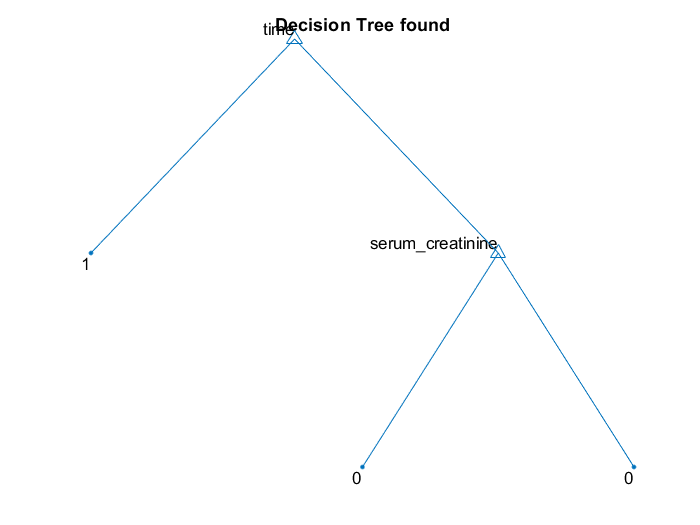

mytree = prune1(tree);
DrawDecisionTree(mytree);

answer = predict(mytree, heart_X_test);
accuracy = myAccuracy(heart_Y_test, answer);
fprintf("Accuracy: %.2f%%\n", accuracy*100);

Accuracy: 89.83%


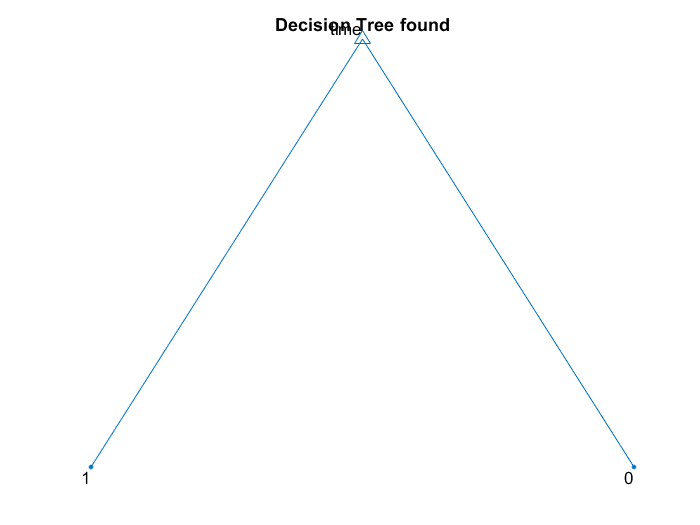

mytree = prune2(mytree);
DrawDecisionTree(mytree);

answer = predict(mytree, heart_X_test);
accuracy = myAccuracy(heart_Y_test, answer);
fprintf("Accuracy: %.2f%%\n", accuracy*100);

Accuracy: 89.83%


function treePruned = prune1(tree)
    tree.kids{1}.kids = [];
    tree.kids{1}.prediction = 1;
    treePruned = tree;
end

function treePruned = prune2(tree)
    tree.kids{2}.kids = [];
    tree.kids{2}.prediction = 0;
    treePruned = tree;
end